clc;clear all;close all;

# DH Phantom X Pincher

%Parámetros DH
ai = [0, -106, 106, 0];
alphai = [deg2rad(-90), deg2rad(0), deg2rad(0), deg2rad(-90)];
di = [93+43, 0, 0, 0];
thetai = {'q1*', 'q2*', 'q3*', 'q4*'};
offset = [deg2rad(0), deg2rad(90), deg2rad(-90), deg2rad(-90)];
table(ai',alphai',di',thetai',offset','VariableNames',{'a (mm)','alpha (rad)','d (mm)','theta (rad)', 'Offset (°)'})

ans = 4×5 table
    a (mm)    alpha (rad)    d (mm)    theta (rad)    Offset (°)
    ______    ___________    ______    ___________    __________

        0       -1.5708       136        {'q1*'}             0  
     -106             0         0        {'q2*'}        1.5708  
      106             0         0        {'q3*'}       -1.5708  
        0       -1.5708         0        {'q4*'}       -1.5708  


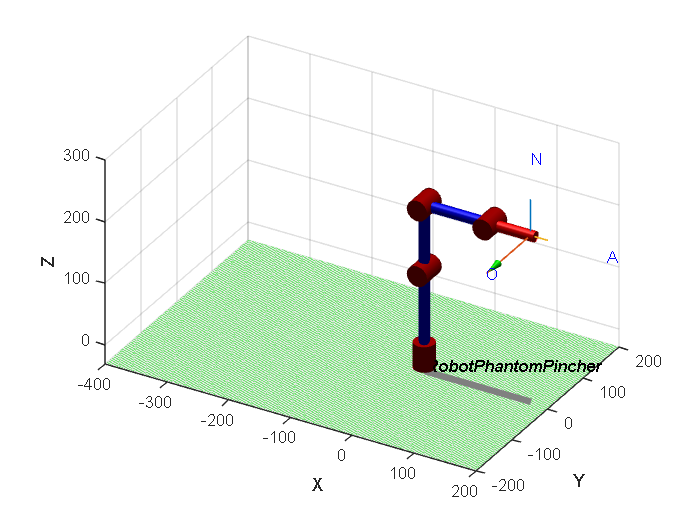

%Diagrama Robot

q = sym('q', [1 4]);
L(1) = Link('revolute','alpha',alphai(1),'a',ai(1),'d',di(1),'offset',offset(1),'qlim',[deg2rad(30) deg2rad(230)]);
L(2) = Link('revolute','alpha',alphai(2),'a',ai(2),'d',di(2),'offset',offset(2),'qlim',[deg2rad(45) deg2rad(255)]);
L(3) = Link('revolute','alpha',alphai(3),'a',ai(3),'d',di(3),'offset',offset(3),'qlim',[deg2rad(10) deg2rad(280)]);
L(4) = Link('revolute','alpha',alphai(4),'a',ai(4),'d',di(4),'offset',offset(4),'qlim',[deg2rad(50) deg2rad(240)]);
Tool = [1 0 0 0; 0 1 0 0; 0 0 1 66; 0 0 0 1];
World = eye(4);
Robot = SerialLink(L,'name','RobotPhantomPincher','tool',Tool,'base',World);
Robot.plot([0 0 0 0],'workspace',[-400 200 -200 200 -30 300],'view',[30 30],'noa')